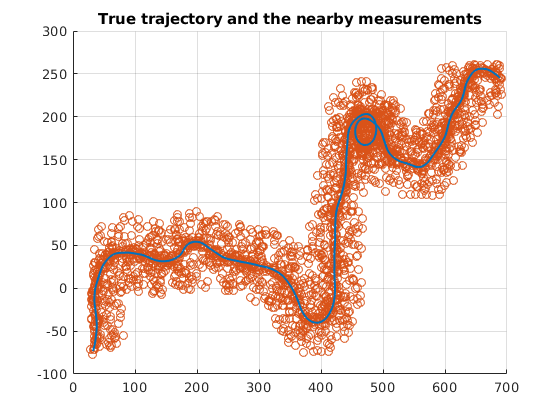

usePregen = true;
if usePregen
    load task5data.mat;
else
    %x0 = [0, 0, 1, 1, 0]';
    %P0 = diag([50, 50, 10, 10, pi/4].^2);
    % model parameters
    %qtrue = [0.25; pi/15].^2;
    %rtrue = 3^2;
    % sampling interval a lenght
    %K = 1000;
    %Ts = 0.1;
    % detection and false alarm
    %PDtrue = 0.9;
    %lambdatrue = 3e-4;
    %rng(10)% can be set for repeatability
    [Xgt, Z, a] = sampleCTtrack(K, Ts, x0, P0, qtrue, rtrue,PDtrue, lambdatrue);
end

% plot measurements close to the trajectory
plotMeasDist = 45;
figure(1); clf; hold on; grid on;
Zplotdata = [];
for k = 1:K
   toPlot = false(size(Z{k},2),1);
   for j = 1:size(Z{k}, 2)
        v = Z{k}(:, j) - Xgt(1:2, k);
        toPlot(j) = v' * v <= plotMeasDist^2;
   end
   Zplotdata = [Zplotdata, Z{k}(:, toPlot)];
end
set(gca, 'ColorOrderIndex', 2)
scatter(Zplotdata(1,:), Zplotdata(2,:));
set(gca, 'ColorOrderIndex', 1)
plot(Xgt(1,:),Xgt(2,:), 'LineWidth',1.5);
title('True trajectory and the nearby measurements')

% % play measurement movie. Remember that you can click the stop button.
% figure(4); clf; grid on;
% set(gcf,'Visible','on')
% plotpause = 0; % sets a pause in between time steps if it goes to fast
% for k = 1:K
%     scatter(Z{k}(1,:), Z{k}(2,:))
%     title(sprintf('measurements at step %d', k))
%     axis([0, 700, -100, 300])
%     grid on;
%     drawnow;
%     pause(plotpause);
% end

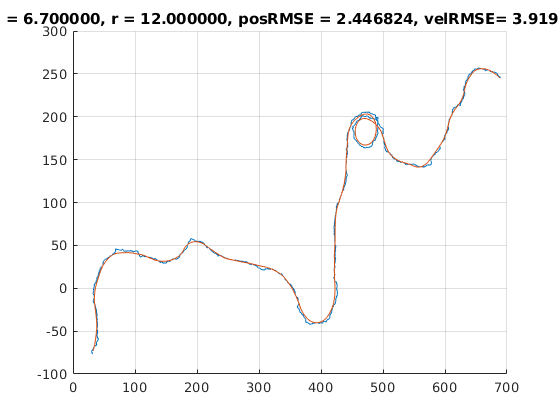

q = 6.7;
r = 12;

PD = 0.75;
lambda = 1e-8;
gatesize = 20;

model = discreteCVmodel(q, r);
ekf = EKF(model);
tracker = PDAF(ekf, lambda, PD, gatesize);

% allocate
xbar = zeros(4, K); % predicted mean
xhat = zeros(4, K); % updated mean
Pbar = zeros(4, 4, K); % predicted cov
Phat = zeros(4, 4, K); % updated cov
NEES = zeros(K, 1);
NEESpos = zeros(K, 1); 
NEESvel = zeros(K, 1);

% initialize
xbar(:, 1) = [Z{1}(:, a(1)); 0; 0]; % first true measurement
Pbar(:, : , 1) = [2*r*eye(2), zeros(2); % slightly overly uncertain position
                  zeros(2), 20^2*eye(2)]; % slightly overerly uncertain velocity

% estimate
for k = 1:K
    [xhat(:, k), Phat(:, :, k)] = tracker.update(Z{k}, xbar(:, k), Pbar(:, :, k)); %... 
    NEES(k) = (Xgt(1:4, k) - xhat(:, k))' * (Phat(:, :, k) \ (Xgt(1:4, k) - xhat(:, k)));
    NEESpos(k) = (Xgt(1:2, k) - xhat(1:2, k))' * (Phat(1:2, 1:2, k) \ (Xgt(1:2, k) - xhat(1:2, k)));
    NEESvel(k) = (Xgt(3:4, k) - xhat(3:4, k))' * (Phat(3:4, 3:4, k) \ (Xgt(3:4, k) - xhat(3:4, k)));
    [xbar(:, k + 1), Pbar(:,:, k + 1)] = tracker.predict(xhat(:, k), Phat(:, :, k), Ts); %...
end

% calculate a performance metric
posRMSE = sqrt(mean(sum((xhat(1:2, :) - Xgt(1:2, :)).^2, 1))); % position RMSE
velRMSE = sqrt(mean(sum((xhat(3:4, :) - Xgt(3:4, :)).^2, 1))); % velocity RMSE

figure(2); clf; hold on; grid on;
plot(xhat(1, :), xhat(2, :));
plot(Xgt(1,:), Xgt(2,:));
title(sprintf('q = %f, r = %f, posRMSE = %f, velRMSE= %f',q, r, posRMSE, velRMSE));

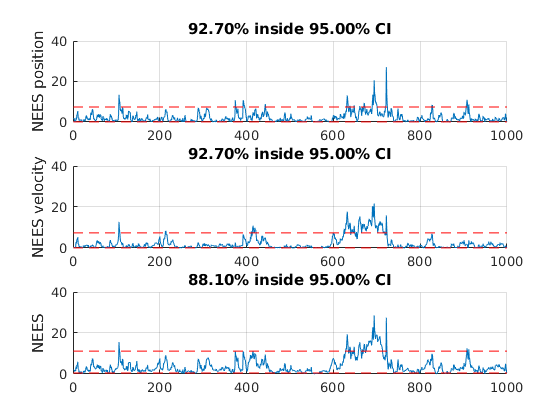


figure(3); clf;
alpha = 0.05;
CI2 = chi2inv([alpha/2, 1 - alpha/2], 2);
CI4 = chi2inv([alpha/2, 1 - alpha/2], 4);

subplot(3,1,1); hold on; grid on;
plot(NEESpos);
plot([1, K],repmat(CI2, 2, 1), 'r--');
ylabel('NEES position')
inCIpos = mean((CI2(1) <= NEESpos) .* (NEESpos <= CI2(2))) * 100;  
title(sprintf('%.2f%% inside %.2f%% CI', inCIpos, (1- alpha) * 100));

subplot(3,1,2); hold on; grid on;
plot(NEESvel)
plot([1, K],repmat(CI2, 2, 1), 'r--');
ylabel('NEES velocity')
inCIvel = mean((CI2(1) <= NEESvel) .* (NEESvel <= CI2(2))) * 100;  
title(sprintf('%.2f%% inside %.2f%% CI', inCIpos, (1- alpha) * 100));

subplot(3,1,3); hold on; grid on;
plot(NEES)
plot([1, K],repmat(CI4, 2, 1), 'r--');
ylabel('NEES')
inCI = mean((CI4(1) <= NEES) .* (NEES <= CI4(2))) * 100;  
title(sprintf('%.2f%% inside %.2f%% CI', inCI, (1- alpha) * 100));


CI2K = chi2inv([0.025, 0.975], 2*K)/K

CI2K =     1.8779    2.1258


ANEESpos = mean(NEESpos)

ANEESpos = 2.2293

ANEESvel = mean(NEESvel)

ANEESvel = 2.3810

CI4K = chi2inv([alpha/2, 1 - alpha/2], 4*K)/K

CI4K =     3.8266    4.1772


ANEES = mean(NEES)

ANEES = 3.8982

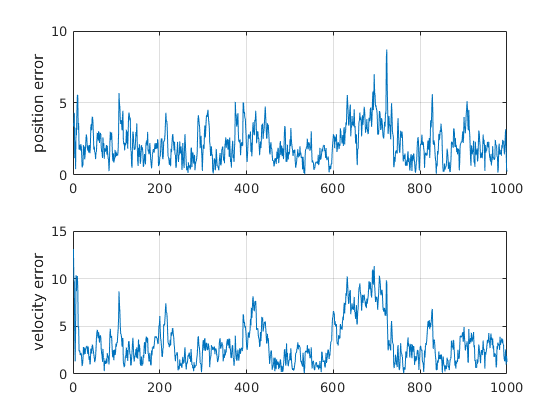


figure(4); clf;
subplot(2,1,1);
plot(sqrt(sum((xhat(1:2, :) - Xgt(1:2, :)).^2, 1)));
grid on;
ylabel('position error')
subplot(2,1,2);
plot(sqrt(sum((xhat(3:4, :) - Xgt(3:4, :)).^2, 1)));
grid on;
ylabel('velocity error')